# Gastrointestinal Cancer Detection - [tutorial](https://blogs.mathworks.com/deep-learning/2019/07/24/deep-learning-for-medical-imaging/)

## Initialize

img_path = "./images/task_2/";

% Image 1
img1 = {0};
img1_path = img_path + "image_1/e9e1cd0e-b6a1-47b5-991d-390d1d3cf28a/TCGA-B9-4116-01A-01-BS1.2e62bc60-29f4-48b9-8fd6-a58b118adf9c.svs";
nrOfImgs_1 = 4; % multi-image file where each image is diff size
for i=1:nrOfImgs_1
    img1{i} = imread(img1_path, i);
    fprintf("Read image layer %d/%d\n", i, nrOfImgs_1);
end

Read image layer 1/4
Read image layer 2/4
Read image layer 3/4
Read image layer 4/4



% Image 2
img2 = {0};
img2_path = img_path + "image_2/6e63430a-4a44-4ba8-a1f9-f24871c8f08a/TCGA-B1-A47M-11A-01-TS1.1E82A92A-DEB4-4690-9D63-52F9EAE59D0D.svs";
nrOfImgs_2 = 4; % multi-image file where each image is diff size
for i=1:nrOfImgs_2
    img2{i} = imread(img2_path, i);
    fprintf("Read image layer %d/%d\n", i, nrOfImgs_2);
end

Read image layer 1/4
Read image layer 2/4
Read image layer 3/4
Read image layer 4/4


## Read Images

The base image (channel 1) is so big that we cannot even look at it... but let's look at some of the smaller images instead.

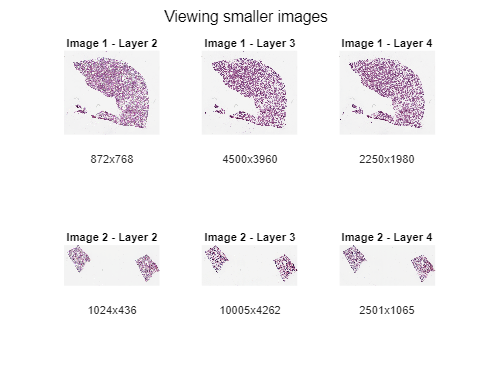

figure;

% Image 1
img1_Info = imfinfo(img1_path); % get the metadata
subplot(2,3,1); imshow(img1{2}); title("Image 1 - Layer 2"); xlabel(num2str(img1_Info(2).Width) + "x" + num2str(img1_Info(2).Height));
subplot(2,3,2); imshow(img1{3}); title("Image 1 - Layer 3"); xlabel(num2str(img1_Info(3).Width) + "x" + num2str(img1_Info(3).Height));
subplot(2,3,3); imshow(img1{4}); title("Image 1 - Layer 4"); xlabel(num2str(img1_Info(4).Width) + "x" + num2str(img1_Info(4).Height));

% Image 2
img2_Info = imfinfo(img2_path); % get the metadata
subplot(2,3,4); imshow(img2{2}); title("Image 2 - Layer 2"); xlabel(num2str(img2_Info(2).Width) + "x" + num2str(img2_Info(2).Height));
subplot(2,3,5); imshow(img2{3}); title("Image 2 - Layer 3"); xlabel(num2str(img2_Info(3).Width) + "x" + num2str(img2_Info(3).Height));
subplot(2,3,6); imshow(img2{4}); title("Image 2 - Layer 4"); xlabel(num2str(img2_Info(4).Width) + "x" + num2str(img2_Info(4).Height));

sgtitle("Viewing smaller images");

## Setting up Alexnet

figure;
net = alexnet; % load an alexnet which is pretrained on ImageNet

allImages = imageDatastore(img_path + 'train_images/', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

Use a different ratio for the data split-up than what is mentioned in the blog --> 35% training, 30% validation, 35% test

*"Split into three sets: 40% training, 20% validation, 40% test"*

[training_set, validation_set, testing_set] = splitEachLabel(allImages,.35,.30,.35); %.4,.2,.4);

### Network modification

Modify the network by **removing the last three layers**. We will **replace these layers with new layers** for our custom classification.

layersTransfer = net.Layers(1:end-3);

Display Labels

training_labels = categories(training_set.Labels);
numClasses = numel(training_labels)

numClasses = 9

labels_desc = ["Adipose Tissue (fat)", "Background (no tissue)", "Debris", ...
    "Lymphocytes", "Mucus", "Muscle", "Normal Mucosa", "Stroma", "Tumor Epithelium"];

disp("Output Categories");

Output Categories


for i=1:size(training_labels, 1)
    disp("  " + training_labels{i} + " - " + labels_desc(i));
end

  ADI - Adipose Tissue (fat)
  BACK - Background (no tissue)
  DEB - Debris
  LYM - Lymphocytes
  MUC - Mucus
  MUS - Muscle
  NORM - Normal Mucosa
  STR - Stroma
  TUM - Tumor Epithelium


We **merge the layers**, and **set the weight and bias learning rate** for the last fully connected layer 'fc'

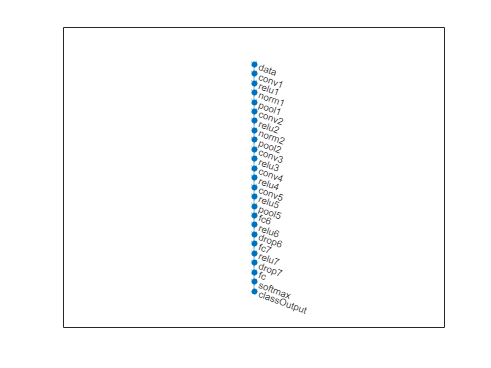

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'Name', 'fc','WeightLearnRateFactor',1,'BiasLearnRateFactor',1)
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classOutput')];

lgraph = layerGraph(layers);
plot(lgraph)

### Modify Training Parameters

We now modify the training set and training options. The training set must be resized to fit the input size expected by the network.

imageInputSize = [227 227 3];
augmented_training_set = augmentedImageDatastore(imageInputSize,training_set)

augmented_training_set =   augmentedImageDatastore with properties:

             NumObservations: 2512
                       Files: {2512×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0



resized_validation_set = augmentedImageDatastore(imageInputSize,validation_set);
resized_testing_set = augmentedImageDatastore(imageInputSize,testing_set);

Set the training options, including plotting the training progress as the network trains.

opts = trainingOptions('sgdm', ...
    'MiniBatchSize', 64,... % mini batch size, limited by GPU RAM, default 100 on Titan, 500 on P6000
    'InitialLearnRate', 1e-5,... % fixed learning rate
    'L2Regularization', 1e-4,... % optimization L2 constraint
    'MaxEpochs',15,... % max. epochs for training, default 3
    'ExecutionEnvironment', 'gpu',...% environment for training and classification, use a compatible GPU
    'ValidationData', resized_validation_set,...
    'Plots', 'training-progress')

opts =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-05
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 15
                   MiniBatchSize: 64
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
            ExecutionEnvironment: 'gpu'
                      WorkerLoad: []
                       OutputFcn: []
                           Plots: 'training-progress'
     

## Training

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:02:30 |        6.25% |        6.45% |       4.9037 |       3.3885 |      1.0000e-05 |
|       2 |          50 |       00:03:15 |       37.50% |       59.97% |       2.1521 |       1.2703 |      1.0000e-05 |
|       3 |         100 |       00:04:00 |       54.69% |       76.07% |       1.4641 |       0.7971 |      1.0000e-05 |
|       4 |         150 |       00:04:44 |       57.81% |       82.28% |       1.2073 |       0.5878 |      1.0000

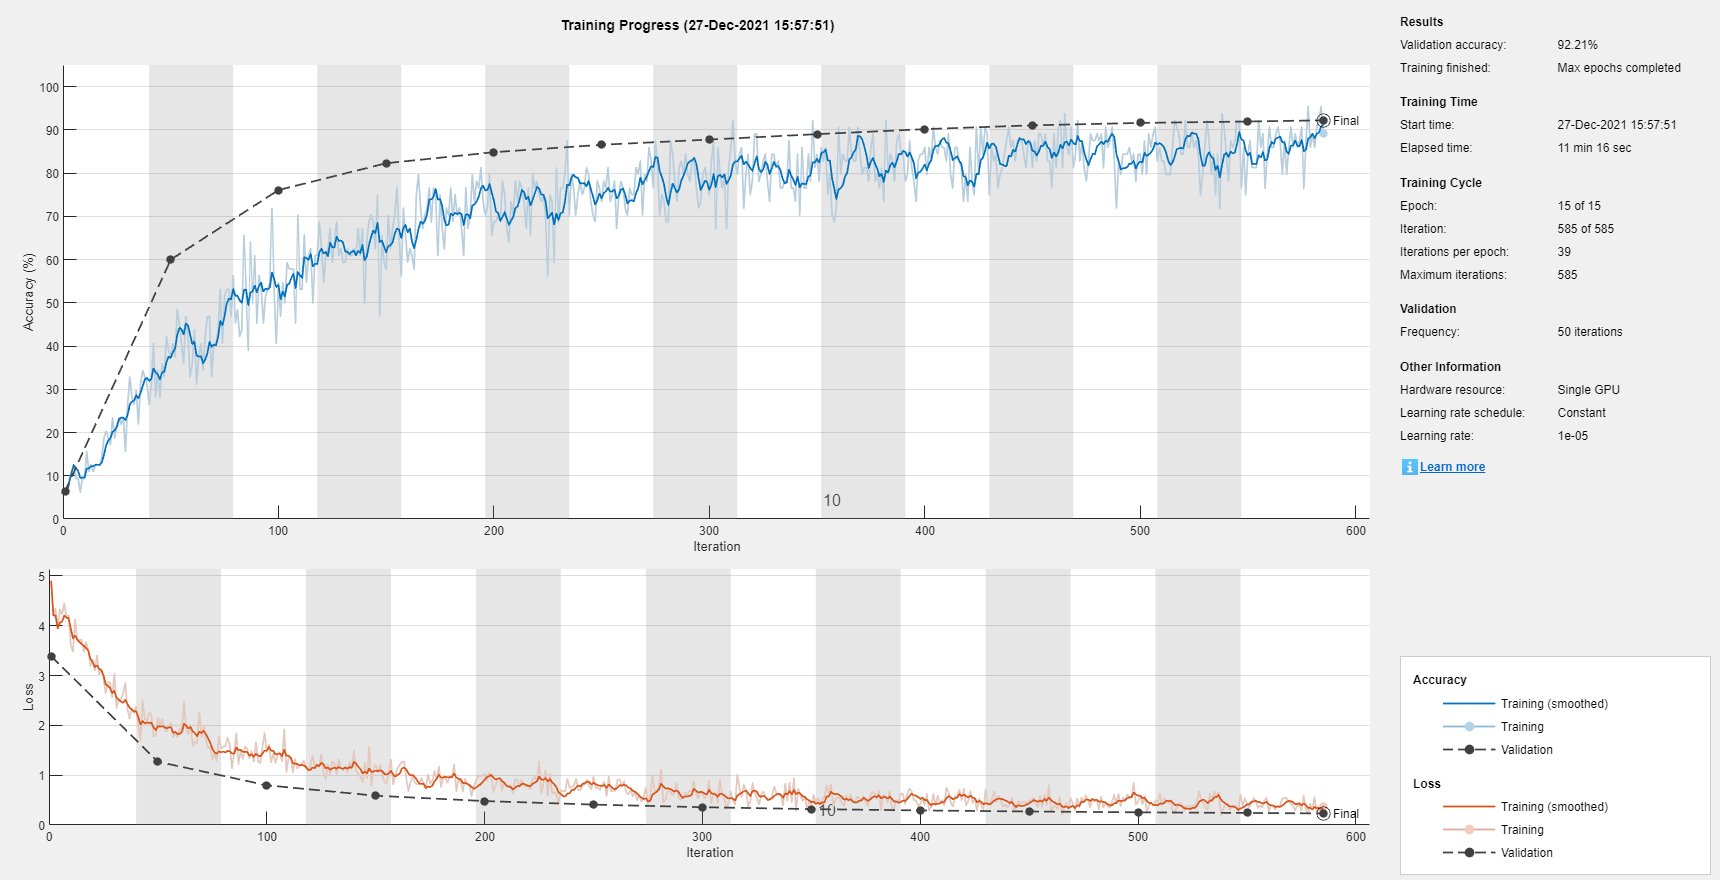

net =   DAGNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
    Connections: [24×2 table]
     InputNames: {'data'}
    OutputNames: {'classOutput'}


net = trainNetwork(augmented_training_set, lgraph, opts)